clear
load('data.mat')

Data filtering

% Find indices of NaN values
nan_indices = isnan(data.parownik);

% Number of NaN values
count=0;
for i=1:length(nan_indices)
    if nan_indices(i,1)==1
        count=count+1;
    end
end
count

count = 3


% Exclude NaN values from the vector
parownik = data.parownik(~nan_indices);

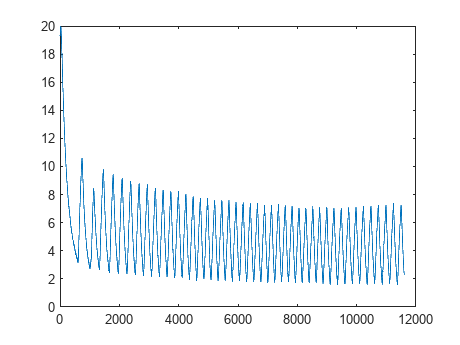

plot(parownik);

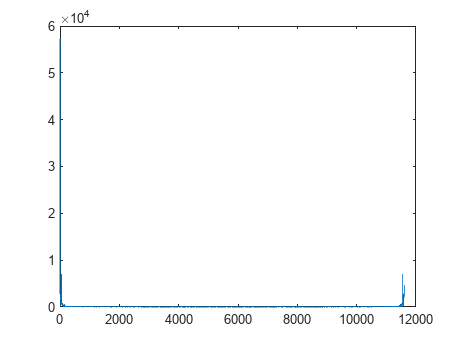

X=fft(parownik);
mag=abs(X);
plot(mag)

Filter desigend in Matlab FilterDesigner and exported into filterF.m script

Hd=filterF;

Filtering

x_filtered=Hd.filter(parownik);

Adjusting the delay and signal gain from filter 

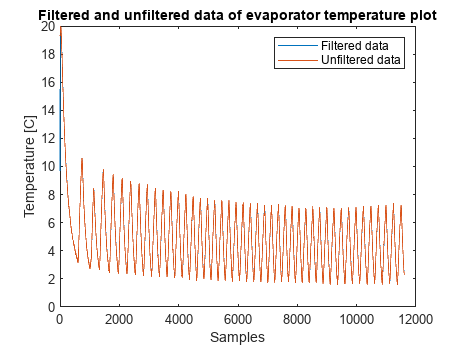

group_delay = floor((length(Hd.Numerator) - 1)/2);
x_filtered = x_filtered(group_delay+1:end);

scale_factor = max(parownik) / max(x_filtered);
x_filtered = x_filtered * scale_factor;



plot(x_filtered);hold on
plot(parownik);hold off
title('Filtered and unfiltered data of evaporator temperature plot')
ylabel('Temperature [C]')
xlabel('Samples')
legend('Filtered data','Unfiltered data');

Other data filtering:

nan_indices = isnan(data.skraplacz);
% Number of NaN values
count=0;
for i=1:length(nan_indices)
    if nan_indices(i,1)==1
        count=count+1;
    end
end
count

count = 3

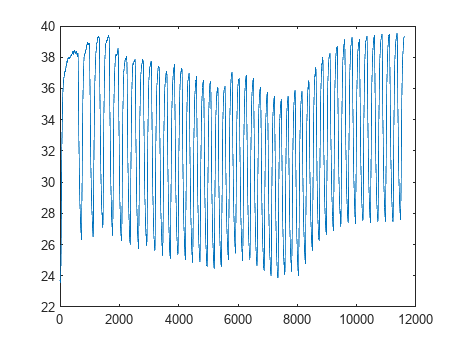

% Exclude NaN values from the vector
skraplacz = data.skraplacz(~nan_indices);
plot(skraplacz);

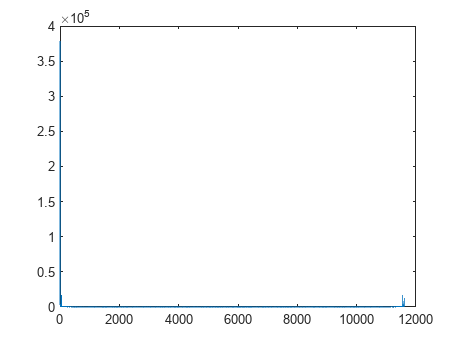

X=fft(skraplacz);
mag=abs(X);
plot(mag)

Filtering

skraplacz_filtered=Hd.filter(skraplacz);

Adjusting the delay and signal gain from filter 

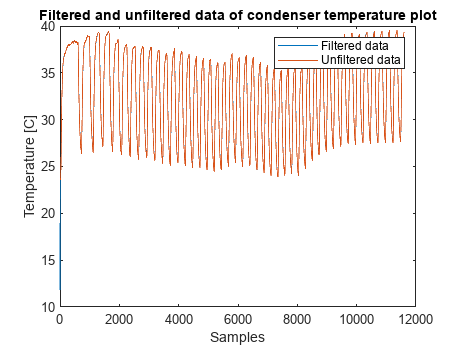

group_delay = floor((length(Hd.Numerator) - 1)/2);
skraplacz_filtered = skraplacz_filtered(group_delay+1:end);

scale_factor = max(skraplacz) / max(skraplacz_filtered);
skraplacz_filtered = skraplacz_filtered * scale_factor;



plot(skraplacz_filtered);hold on
plot(skraplacz);hold off
title('Filtered and unfiltered data of condenser temperature plot')
ylabel('Temperature [C]')
xlabel('Samples')
legend('Filtered data','Unfiltered data');

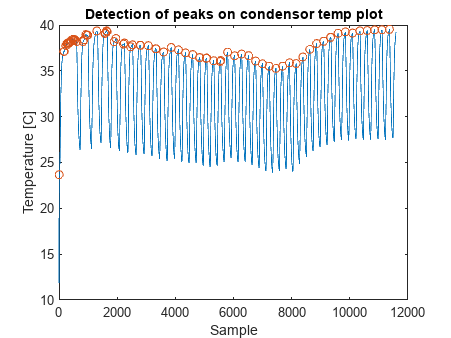

[pks,locs] = findpeaks(skraplacz_filtered);
n=length(skraplacz_filtered);
x=1:n;
plot(x,skraplacz_filtered);hold on;
plot(x(locs),pks,"o");hold off
title('Detection of peaks on condensor temp plot')
xlabel('Sample')
ylabel('Temperature [C]')

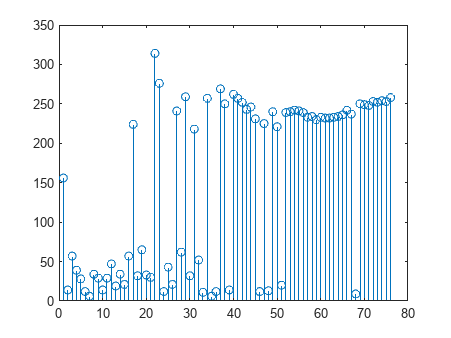

n_locs=length(locs);
f1=zeros(n_locs-1,1);
f3=f1;
f2=zeros(n_locs-1,2);
for i=1:n_locs-1
    f1(i)=locs(i+1)-locs(i);
    f2(i,:)=[max(skraplacz_filtered(locs(i):locs(i+1))),...
        min(skraplacz_filtered(locs(i):locs(i+1)))];
    f3(i)=mean(skraplacz_filtered(locs(i):locs(i+1)));
end

stem(f1);

Conclusion:

From readings from condenser it is less reliable to detect cycle using this technique. Tweeking the filter (much lower passband) might solve the problem.

Right now it's not necessary, because we already detected the location of peaks from the evaporator reading. We'll use that clasification method from now on.